## Least square fit polynomials

Given the table, 


$$\begin{array}{r|l|l|c|l|}
x & x_{1} & x_{2} & \cdots & x_{N}\\ \hline
y & y_{1} & y_{2} & \cdots & y_{N}
\end{array}$$


where, wlog, we can assume $x_{1} < x_{2} < \dots < x_{N}$. We look for a polynomial $P_{n}\in\mathbb{R}_{n}[x]$ of degree $n$, $n<N$, $P_{n}(x) = p_{1}x^{n} + p_{2} x^{n-1} + p_{3} x^{n-2} + \dots + p_{n} x + p_{n+1}$s.t., 


$$\sqrt{\sum_{i=1}^{N} \left(y_{i} - P_{n}(x_{i})\right)^{2}} \le \sqrt{\sum_{i=1}^{N} \left(y_{i} - Q_{n}(x_{i})\right)^{2}},$$


for all other polynomials $Q_{n}\in\mathbb{R}_{n}[x]$, $Q_{n}(x) = q_{1}x^{n} + q_{2} x^{n-1} + q_{3} x^{n-2} + \dots + q_{n} x + q_{n+1}$, of degree $n < N$. The polynomials $P_{n}$, $n=1,2,\dots,N-1$ are called the polynomials of the *least square approximation, *or of the *least square fit *(lsf) of degree $n$. In particular, $P_{N-1}$is the *interpolation polynomial*, and satisfies


$$P_{N-1}(x_{i}) = y_{i}, \qquad i=1,\dots,N.$$


In Matlab the coefficients of the polynomial of the lsf polynomial can be computed using the function `polyfit`:

Later, to evaluate these polynomial in a set of abscisses, we use the function `polyval`. For example, 

**Example. **Let us consider the function

$f(x) = \mathrm{e}^{x/2}\sin(2x)$,

on the interval $-1\le x\le 1$, and a sample of points given by the abscisses $x_{i} = -1 + 0.2(i-1)$, and their corresponding values $y=f(y_{i})$, $i=1,\dots,N=11$.

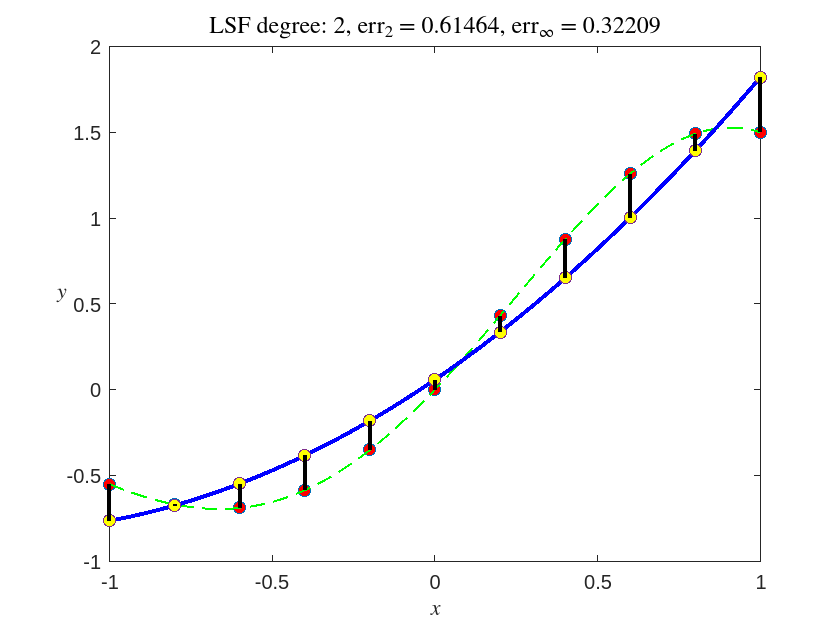

clearvars
close all

f = @(x) exp(x/2).*sin(2*x);
%f = @(x) 1./(1+x.^2);
%f = @(x) 1./(1+25*x.^2); %Runge phenomenon....
a = -1; b = 1; numSamplePoints = 11; degree = 2;

h = (b-a)/(numSamplePoints-1);

%Table
dataX = -1:h:1;
dataY= f(dataX);

%Points we shall use to plot
delta=0.01;
x = a:delta:b;
%numPlotPoints = floor((b-a)/delta)+1;
%x = linspace(a,b,numPlotPoints);

%Plot sample
plot(dataX, dataY, 'o', 'MarkerFaceColor','red', 'MarkerSize', 6)
hold on
y=f(x);
plot(x,y,'--','color','green','LineWidth',1);
%lsf polynomial: polyfit
p = polyfit(dataX,dataY,degree);
%p(1) = p(1) + 0.01;  %Test: change a bit one of the coefficients

%Plot
yPol = polyval(p,x);              
yPolAtDataX = polyval(p,dataX);

plot(x, yPol,'-','Color','blue','LineWidth', 2)
plot(dataX,yPolAtDataX,'o','MarkerFaceColor','yellow','MarkerSize',6)

for i=1:length(dataX)  %to plot the "error" vertical segments
    line=[dataX(i), dataY(i);
        dataX(i), yPolAtDataX(i)];
    plot(line(:,1), line(:,2),'-','color','black','lineWidth',2)
end
errSQRT = norm(yPolAtDataX-dataY,2);    %Error (norm-2) 
errINF = norm(yPolAtDataX-dataY,Inf);   %Error (norm-INF)

set(gcf,'defaultTextInterpreter','LaTeX')
title(['LSF degree: ', num2str(degree),...
    ', err$_{2}$ = ',num2str(errSQRT), ...
    ', err$_\infty$ = ', num2str(errINF)],...
    'FontSize',12)
xlabel('$$x$$')
ylabel('$$y$$','rot',360)
hold off

fprintf('degree: %d, lsf-err(norm-2): %e, lsf-err(norm-inf) : %e\n', ...
    degree,errSQRT,errINF)

degree: 2, lsf-err(norm-2): 6.146395e-01, lsf-err(norm-inf) : 3.220872e-01
